# FFT2 of phantoms to check Kmap

% REAL PHANTOM
% First check particle velocity

dinf.fc = Trans.frequency*1e6;
dinf.c0 = 1540; dinf.wl = dinf.c0/dinf.fc;
dinf.dz = PData(1).PDelta(3)*dinf.wl;
dinf.dx = PData(1).PDelta(1)*dinf.wl;
dinf.samplesRF = 2048; dinf.PRFe = 10*300;
dinf.Tprf = 1/dinf.PRFe; dinf.Troundtrip = (dinf.samplesRF/2)*(1/dinf.fc);
dinf.maxDepth = dinf.Troundtrip*dinf.c0/2;
dinf.fs = dinf.PRFe; fs = dinf.PRFe;dinf.offset_y = 0; 

IQFrame = IQData1(:,:,end); % last frame
Bmode = 20*log10(abs(IQFrame(:,:,1)));
Bmode = Bmode - max(Bmode(:));

dinf.num_angles = 1;
dinf.offset_z = dinf.dz*size(IQFrame,1)/2;

[u,dinf] = pv_cal(IQData1,dinf, dinf.num_angles); 

Calculating particle velocity signals...


u = signal_period(freq, dinf.PRFe, u);  

% create_pv_movie(u, dinf, 10, freq, 0);

Video creation complete!



% Temperal filtering process, a bandpass FIR filter is used around 
% +- 20 Hz the vibration frequency
cs_min = 0.7; % [m/s]
cs_max = 8;   % [m/s]
f_tol = 10;   % [Hz] tolerance for +/-2*f_tol
% This function uses spatial_fil_phase_extrac inside

[u_new, Frames0, Frames1] = u_filt(u, freq, f_tol, dinf, cs_min, cs_max);  

create_pv_movie(u_new, dinf, 10, freq, 1);

Video creation complete!


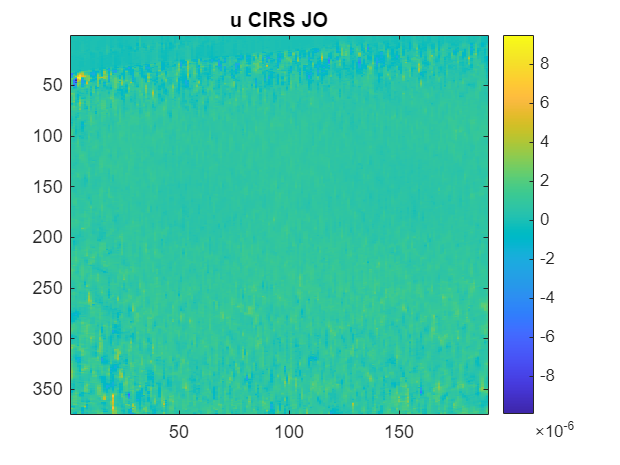


figure, 
imagesc(real(u(:,:,10))),
colorbar
title('u CIRS JO')


% u = u_phantom;
% figure, 
% imagesc(real(u_new(:,:,8)))
% title('u phantom lim')





x = xdim;
z = ydim;

cs_min = 1; cs_max = 8;
calc_wvlength_k(cs_min, freq, dinf);

SWS: 1.00 [m/s] | Freq: 700 [Hz] | K: 4398.00 [rad/m] | wvlength:  1.00 [mm] | Window size Ax: 9 | La: 9 


calc_wvlength_k(cs_max, freq, dinf);

SWS: 8.00 [m/s] | Freq: 700 [Hz] | K: 550.00 [rad/m] | wvlength:  11.00 [mm] | Window size Ax: 75 | La: 75 


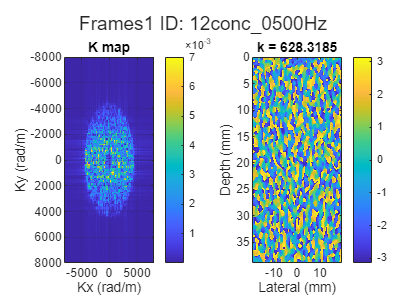



[u_new, Frames0, Frames1, u_freq] = u_filt(u_phantom, freq, f_tol, dinf, cs_min, cs_max);

% [u_filt_v2] = fun_JO_v2(u, freq, dinf, cs_min, cs_max);
% [M_filtered, u_filt_v2] = fun_JO_v1(u, freq, dinf);
% [M_filtered, u_filt_v2] = fun_JO_v2(u, freq, dinf, cs_min, cs_max);

space_map = Frames0;

[Ny, Nx, ~] = size(space_map);

% Define the spatial sampling intervals (assuming equal spacing)
dx = dinf.dx;  % Example spatial resolution in meters
dy = dinf.dz;  % Assume square grid for simplicity

% Compute the wavenumber ranges
kx = (-Nx/2:Nx/2-1) * (2*pi / (Nx * dx));
ky = (-Ny/2:Ny/2-1) * (2*pi / (Ny * dy));

% Create the wavenumber grid
[KX, KY] = meshgrid(kx, ky); 


% Perform the 2D FFT and shift the zero-frequency component to the center
kmap = fftshift( fft2(space_map) );
abs_kmap = abs(kmap);


figure, 
tiledlayout(1,2);
% set(gcf, 'units', 'Normalized', 'Position', [0 0.1 0.8 0.55])
sgtitle(['Frames1 ID: ', idName], 'Interpreter', 'none')

nexttile
imagesc( kx, ky, log(1+abs_kmap)  ), grid on;
colorbar, 
title('K map')
xlabel('Kx (rad/m)'), ylabel('Ky (rad/m)')
xlim([-8000 8000])
ylim([-8000 8000])

nexttile
imagesc( x*1e3, z*1e3, angle(space_map)  );
colorbar, 
title(['k = ', num2str(wvnumber)])
xlabel('Lateral (mm)'), ylabel('Depth (mm)')

% xlim([-5000 5000])
% ylim([-5000 5000])


space_map = Frames1; 
x = xdim;
y = ydim;
[Ny, Nx, ~] = size(space_map);
% Define the spatial sampling intervals (assuming equal spacing)
dx = dinf.dx;  % Example spatial resolution in meters
dy = dinf.dz;  % Assume square grid for simplicity

% Perform the 2D FFT and shift the zero-frequency component to the center
kmap = fftshift( fft2(space_map) );
abs_kmap = abs(kmap);

kx = (-Nx/2:Nx/2-1) * (2*pi / (Nx * dx));
ky = (-Ny/2:Ny/2-1) * (2*pi / (Ny * dy));

figure,
tiledlayout(1,3)

imagesc( x*1e3, z*1e3, angle(space_map)  );
colorbar, 
title(['k = ', num2str(wvnumber)])
xlabel('Lateral (mm)'), ylabel('Depth (mm)')
% xlim([-5000 5000])
% ylim([-5000 5000])


nexttile
imagesc(kx, ky, abs_kmap), colorbar, colormap("parula")
% imagesc(kx, ky, Hd), colorbar
xlabel('Kx (rad/m)'), ylabel('Ky (rad/m)')
title('|H|')
xlim([-5000 5000])
ylim([-5000 5000])

nexttile
Fsx = 1/dx; Fsy = 1/dy;
kx_m = -Fsx/2: Fsx/Nx : Fsx/2 - Fsx/Nx; % (-N/2: N/2-1) * Fs/N
ky_m = -Fsy/2: Fsy/Ny : Fsy/2 - Fsx/Ny;

imagesc(kx_m*1e-3, ky_m*1e-3,abs_kmap), colorbar, colormap("parula")
% imagesc(kx, ky, Hd), colorbar
xlabel('Kx (1/mm)'), ylabel('Ky (1/mm)')
title('|H|')
xlim([-2 2])
ylim([-2 2])



figure, 
sgtitle(['\theta: ', num2str(theta)])

subplot(421), imagesc(area_x), title('x'), colorbar
subplot(422), imagesc(area_z), title('z'), colorbar
subplot(423), imagesc(rotated_area_x), title('Rot x'), colorbar
subplot(424), imagesc(rotated_area_z), title('Rot z'), colorbar
subplot(425), imagesc(diff_area_x), title('\nabla x'), colorbar
subplot(426), imagesc(diff_area_z), title('\nabla z'), colorbar

subplot(4,2,7),
imagesc(aux), title('||\nabla||_2'), colorbar

subplot(4,2,8),
imagesc(val_abs_3D(:, :, idx)), title('MedFil ||\nabla||_2'), colorbar
%%
figure
for i = 1:size(val_abs_3D,3)
    subplot(2,3,i)
    imagesc(val_abs_3D(:,:,i))

end

subplot(2,3,6)
aa = mean(val_abs_3D, 3);
imagesc(aa)
aa_med = median(aa, 'all');
title('Med val =', num2str(aa_med))

[JO_filtered_v2] = fun_JO_v2(u, freq, dinf);
%%

Bmode = 20*log10(abs(IQBmodeData(:,:,1)));
Bmode = Bmode - max(Bmode(:));

xdim = linspace(-dinf.dx*size(Bmode,2)/2,dinf.dx*size(Bmode,2)/2,size(Bmode,2)); 
ydim = linspace(0,dinf.dz*size(Bmode,1),size(Bmode,1));

%% CURVE FITTING OG
win = [31 15];
correc = xcorr2(ones(win(1), win(2))); % it is default 
dx = dinf.dx; dz = dinf.dz;

pv_field = angle(JO_filtered);

og_size = size(pv_field);
mirror_pv = padarray(pv_field, (win-1)/2, 'symmetric','both');

tic 
% [Kx,Kz,Rx,Rz] = sws_estimation_curve_fitting(mirror_pv, win, dx , dz, correc);
% [Kx,Kz,Rx,Rz] = sws_estimation_cf(mirror_pv, win, dx, dz, correc);

% [Kx,Kz,Rx,Rz, K1d, R1d] = sws_estimation_cf(mirror_pv, win, dx, dz, correc); % GILMER
[Kx,Kz,Rx,Rz, K1d, R1d] = sws_estimation_cf_fast(mirror_pv, win, dx, dz, correc, og_size); % EMZ
wvnumber = 1000;
tt = toc;
fprintf('Time passed CF %.4f\n', tt)

figure, 
sgtitle(['Win = ', num2str(win)])
axis_k = [0 10*wvnumber];
subplot(2,3,1), imagesc(real(Kx), axis_k), colorbar, title('Kx')
subplot(2,3,2), imagesc(real(Kz), axis_k), colorbar, title('Kz')
subplot(2,3,3), imagesc(real(K1d), axis_k), colorbar, title('K1d')

subplot(2,3,4), imagesc(real(Rx)), colorbar, title('Rx')
subplot(2,3,5), imagesc(real(Rz)), colorbar, title('Rz')
subplot(2,3,6), imagesc(real(R1d)), colorbar, title('R1d')

%
sws_cf_lat = 2*pi*freq./Kx;
sws_cf_axi = 2*pi*freq./Kz;
sws_cf_both = 2*pi*freq./( 0.5*(Kz+Kx)  );
sws_cf_1d = 2*pi*freq./K1d;

figure, 
sgtitle(['Win = ', num2str(win)])
subplot(2,2,1), imagesc(sws_cf_lat, [0 4]), title('SWS lat'), colormap("jet"), colorbar
subplot(2,2,2), imagesc(sws_cf_axi, [0 4]), title('SWS axi'), colormap("jet"), colorbar
subplot(2,2,3), imagesc(sws_cf_both, [0 4]), title('SWS both'), colormap("jet"), colorbar
subplot(2,2,4), imagesc(sws_cf_1d, [0 4]), title('SWS 1d'), colormap("jet"), colorbar


%
%% CURVE FITTING OG
win = [31 15];
correc = xcorr2(ones(win(1), win(2))); % it is default 
dx = dinf.dx; dz = dinf.dz;

pv_field = angle(JO_filtered_T);

og_size = size(pv_field);
mirror_pv = padarray(pv_field, (win-1)/2, 'symmetric','both');

tic 
% [Kx,Kz,Rx,Rz] = sws_estimation_curve_fitting(mirror_pv, win, dx , dz, correc);
% [Kx,Kz,Rx,Rz] = sws_estimation_cf(mirror_pv, win, dx, dz, correc);

% [Kx,Kz,Rx,Rz, K1d, R1d] = sws_estimation_cf(mirror_pv, win, dx, dz, correc); % GILMER
[Kx,Kz,Rx,Rz, K1d, R1d] = sws_estimation_cf_fast(mirror_pv, win, dx, dz, correc, og_size); % EMZ
wvnumber = 1000;
tt = toc;
fprintf('Time passed CF %.4f\n', tt)

figure, 
sgtitle(['Win = ', num2str(win)])
axis_k = [0 10*wvnumber];
subplot(2,3,1), imagesc(real(Kx), axis_k), colorbar, title('Kx')
subplot(2,3,2), imagesc(real(Kz), axis_k), colorbar, title('Kz')
subplot(2,3,3), imagesc(real(K1d), axis_k), colorbar, title('K1d')

subplot(2,3,4), imagesc(real(Rx)), colorbar, title('Rx')
subplot(2,3,5), imagesc(real(Rz)), colorbar, title('Rz')
subplot(2,3,6), imagesc(real(R1d)), colorbar, title('R1d')

%
sws_cf_lat = 2*pi*freq./Kx;
sws_cf_axi = 2*pi*freq./Kz;
sws_cf_both = 2*pi*freq./( 0.5*(Kz+Kx)  );
sws_cf_1d = 2*pi*freq./K1d;

figure, 
sgtitle(['Win = ', num2str(win)])
subplot(2,2,1), imagesc(sws_cf_lat, [0 4]), title('SWS lat'), colormap("jet"), colorbar
subplot(2,2,2), imagesc(sws_cf_axi, [0 4]), title('SWS axi'), colormap("jet"), colorbar
subplot(2,2,3), imagesc(sws_cf_both, [0 4]), title('SWS both'), colormap("jet"), colorbar
subplot(2,2,4), imagesc(sws_cf_1d, [0 4]), title('SWS 1d'), colormap("jet"), colorbar


% v1

img = imread('gantrycrane.png');
dy = 1E-3; 
dx = 2E-3;
[Ny, Nx, ~] = size(img);

kx = (-Nx/2:Nx/2-1) * (2*pi / (Nx * dx));
ky = (-Ny/2:Ny/2-1) * (2*pi / (Ny * dy));


% v2
Fs_y = 1/dy;  % Sampling spatial frequency
Fs_x = 1/dx;

[KX, KY] = freqspace([Ny, Nx],'meshgrid'); % [-1 1]
KX_m = KX*(Fs_x/2); % [1/m]
KY_m = KY*(Fs_y/2); % [1/m]

KX_rad = KX_m*2*pi; % [rad/m]
KY_rad = KY_m*2*pi; % [rad/m]

ky_rad = KY_rad(:,1);
kx_rad = KX_rad(1,:);

figure, 
plot(kx, 'DisplayName', 'kx v1')
hold on
plot(kx_rad, 'DisplayName', 'kx v2')
plot(kx-kx_rad, 'DisplayName', 'error')
hold off
legend()
